# Control and Instrumentation Lab Assignment 4

**Swarnendu Paul 19EE3FP18**

**Q1.**

Given transfer function

$M(s)=\frac{20(s-1)}{(s+2)(s^2+4)}$ has poles at $-2,\pm2j$  

As the system has 2 poles on imaginary axis and one pole in LHP, so it is

**marginally stable**, that we can observe from the impulse response of the transfer function.

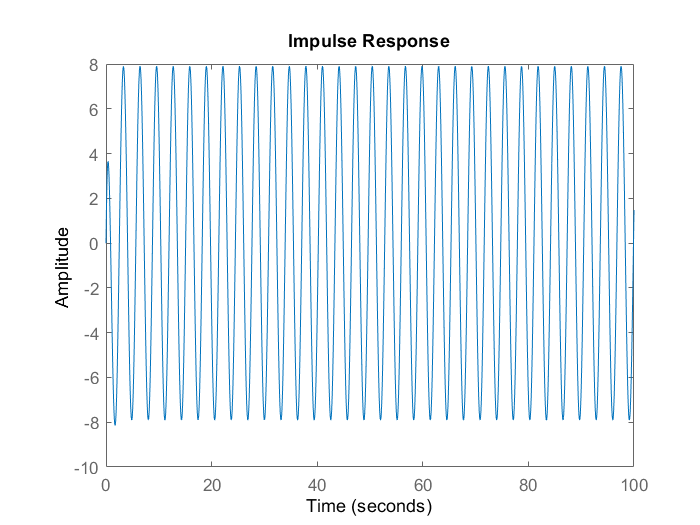

tf1=zpk(1,[-2,2i,-2i],20);
impulse(tf1,100)

**Q2.**

Characteristic equation,


$$2s^4+s^3+3s^2+5s+10=0$$


Solving using Routh-Hurwitz criterion we get,

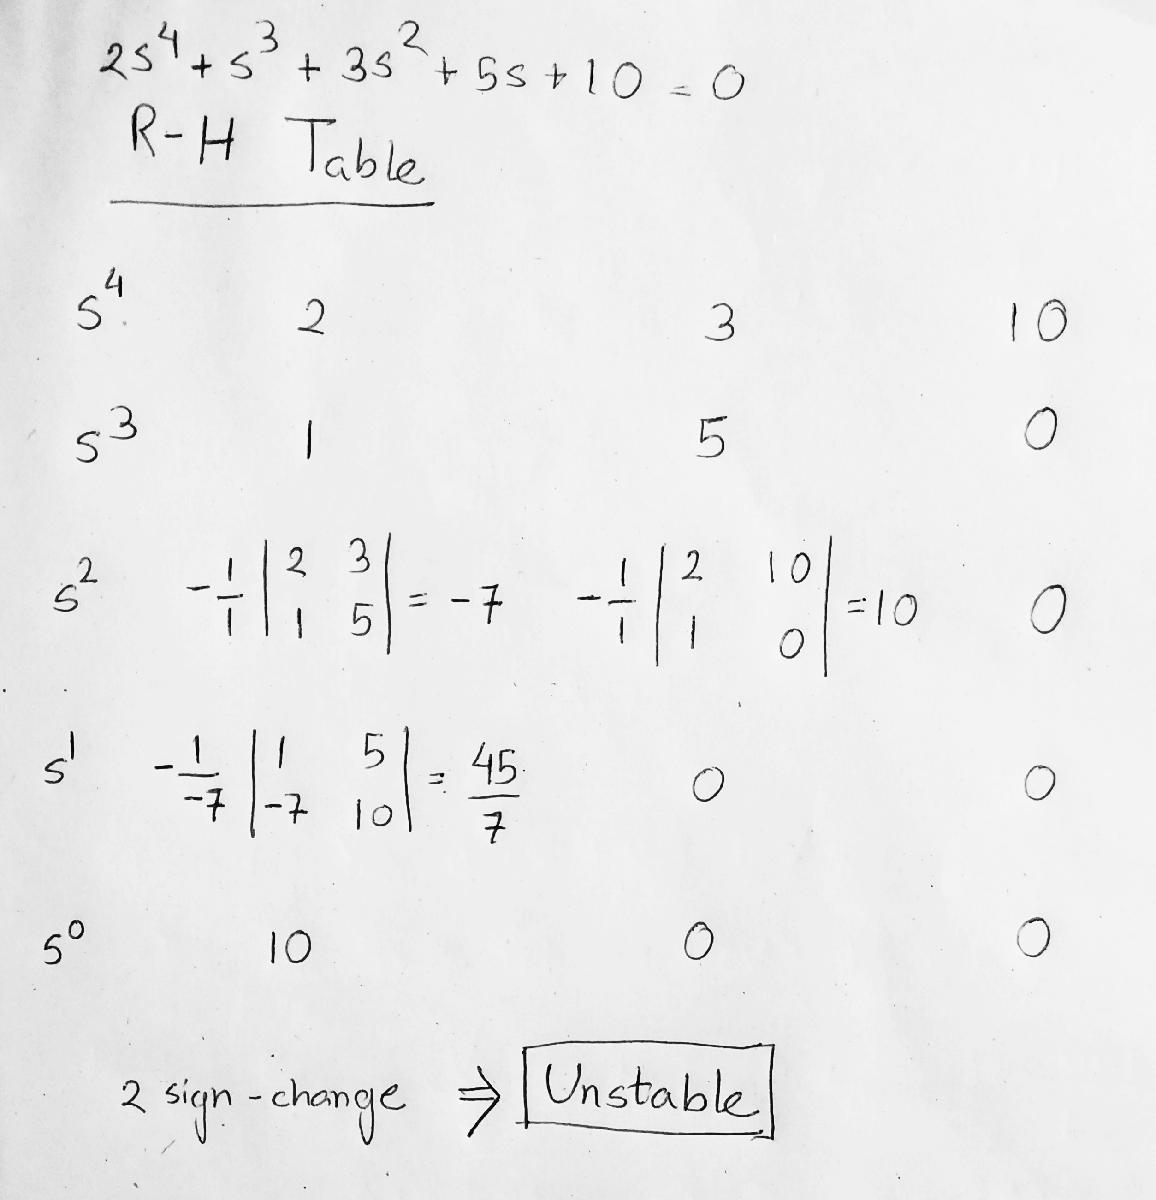

Now we implement the Routh-Hurwitz external fuction to find the stability of the given characteristic equation. In the defined function, first  input is the coefficient of characteristic polynomial. And the 2nd input prints the RH Table when input is 1.

y1=rhc([2,1,3,5,10],1);


 Routh-Hurwitz Table:


rhTable =     2.0000    3.0000   10.0000
    1.0000    5.0000         0
   -7.0000   10.0000         0
    6.4286         0         0
   10.0000         0         0


if y1==0
    fprintf("System is unstable \n")
else
    fprintf("System is stable \n")
end

System is unstable 


**Q3.**

Characteristic equation,


$$s^4+s^3+2s^2+2s+3=0$$


Using the rhc function defined to calculate the RH Table,

y2=rhc([1,1,2,2,3],1);


 Routh-Hurwitz Table:


rhTable = 	1.0e+04 *

    0.0001    0.0002    0.0003
    0.0001    0.0002         0
    0.0000    0.0003         0
   -2.9998         0         0
    0.0003         0         0


if y2==0
    fprintf("System is unstable \n")
else
    fprintf("System is stable \n")
end

System is unstable 


**Q4. **

Characteristic equation,


$$s^5+4s^4+8s^3+8s^2+7s+4=0$$


Using the rhc function defined to calculate the RH Table,

y3=rhc([1,4,8,8,7,4],1);


 Routh-Hurwitz Table:


rhTable =     1.0000    8.0000    7.0000
    4.0000    8.0000    4.0000
    6.0000    6.0000         0
    4.0000    4.0000         0
    0.0001         0         0
    4.0000         0         0


if y3==0
    fprintf("System is unstable \n")
else
    fprintf("System is stable \n")
end

System is stable 


Although the system is **marginally stable** as we observe that one value in 1st column of routh table is 0. 